% Modelo de energía, potencial y Lagrangiano robot planar 1GDL
% Erik García Cruz A01732440
% ----


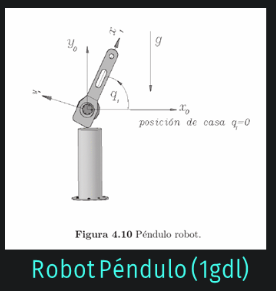


%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) % th2(t) th3(t)  t   %Angulos de cada articulación
syms th1p(t) % th2p(t) th3p(t)   %Velocidades de cada articulación
syms th1pp(t) % th2pp(t) th3pp(t) %Aceleraciones de cada articulación
syms m1 Ixx1 Iyy1 Izz1 % m2 m3 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3  %Masas y matrices de Inercia
syms l1 lc1 % l2 l3 lc2 lc3 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [th1]; % th2; th3];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p]; % th2p; th3p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp]; % th2pp; th3pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 ]; % 0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

%Articulación 2
%Posición de la articulación 2 respecto a 1
%P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
%R(:,:,2)= [cos(th2) -sin(th2)  0;
%           sin(th2)  cos(th2)  0;
%           0         0         1];

%Articulación 3
%Posición de la articulación 2 respecto a 1
%P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];
%Matriz de rotación de la junta 1 respecto a 0
%R(:,:,3)= [cos(th3) -sin(th3)  0;
%           sin(th3)  cos(th3)  0;
%           0         0         1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%CALCULAMOS LAS VELOCIDADES PARA CADA ESLABÓN : 1, 2, 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 1  %%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL)=PO(:,:,GDL);
Jw_a1(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify (Jv_a1*Qp(1:1));
pretty(V1)

/ -l1 sin(th1(t)) th1p(1) \
|                         |
|  l1 cos(th1(t)) th1p(1) |
|                         |
\            0            /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1:1));
pretty(W1)

/    0    \
|         |
|    0    |
|         |
\ th1p(1) /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%% Omitimos la división de cada lc %%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 %P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
 %P23=subs(P(:,:,3), l3, lc3);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

%I2=[Ixx2 0 0; 
%    0 Iyy2 0; 
%    0 0 Izz2];

%I3=[Ixx3 0 0; 
%    0 Iyy3 0; 
%    0 0 Izz3];

%Función de energía cinética

%Calculamos la energía cinética para cada uno de los eslabones%%%%%%%%%%

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1); % Formula general de la energía cinetica 1/2 * m*v^2
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

             _______       ______                   __ _______                     2           2
Izz1 th1p(1) th1p(1)   cos(th1(t) - th1(t)) th1p(1) m1 th1p(1) (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
-------------------- + --------------------------------------------------------------------------
          2                                             2 l1 lc1





%Eslabón 2
%V2_Total= V2+cross(W2,P12);
%K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
%disp('Energía Cinética en el Eslabón 2');
%K2= simplify (K2);
%pretty (K2);

%Eslabón 3
%V3_Total= V3+cross(W3,P23);
%K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I2*W3);
%disp('Energía Cinética en el Eslabón 3');
%K3= simplify (K3);
%pretty (K3);



%K_Total= simplify (K1+K2+K3);
K_Total = K1;
disp('Energía Cinética Total');

Energía Cinética Total


pretty (K_Total);

             _______       ______                   __ _______                     2           2
Izz1 th1p(1) th1p(1)   cos(th1(t) - th1(t)) th1p(1) m1 th1p(1) (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
-------------------- + --------------------------------------------------------------------------
          2                                             2 l1 lc1




%Energia Potencial  p=mgh

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje z
 %h2= P12(2); %Tomo la altura paralela al eje y
 %h3= P23(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1

$$U1 = g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)$$

 %U2=m2*g*h2
 %U3=m3*g*h3

 %Calculamos la energía potencial total
 %U_Total= U1 + U2 +U3;
 U_Total= U1;

 %Obtenemos el Lagrangiano
 disp('Lagrangiano');

Lagrangiano


 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

             _______                              ______                   __ _______                     2           2
Izz1 th1p(1) th1p(1)                          cos(th1(t) - th1(t)) th1p(1) m1 th1p(1) (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
-------------------- - g lc1 m1 sin(th1(t)) + --------------------------------------------------------------------------
          2                                                                    2 l1 lc1




%Modelo de Energía
disp('Modelo de energía total');

Modelo de energía total


 H= simplify (K_Total+U_Total);
  pretty (H)

             _______                              ______                   __ _______                     2           2
Izz1 th1p(1) th1p(1)                          cos(th1(t) - th1(t)) th1p(1) m1 th1p(1) (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
-------------------- + g lc1 m1 sin(th1(t)) + --------------------------------------------------------------------------
          2                                                                    2 l1 lc1

